#### Autori: Daniele Randazzo (4377397) , Mohammad Reza Haji Hosseini (4394567)

#### Gruppo: 1D

# Bioconcentration

### Introduzione

Il progetto svolto si pone di valutare come delle sostanze chimiche vengono distribuite all'interno dell'organismo, ed in particolare, se sono o meno principalmente concentrate all'interno di tessuti lipidici, se vi sono eventuali siti di immagazzinamento addizionali, come siti proteici, o se la sostanza in questione viene metabolizzata oppure eliminata.

Per fare questo, per ogni sostanza a disposizione risulta necessario conoscerne la sua bioconcentrazione, che riflette appunto l'incremento di agenti chimici mediante la cute e le superfici respiratorie.

Per quantificare questo fenomeno, molti quadri normativi utilizzano il Bioconcentration Factor (BCF), ovvero una costante di proporzionalità ricavata dal confronto della concentrazione della sostanza all'interno di un determinato organismo, con quella che si trova nell'acqua allo stato stazionario.

In base al valore di BCF, le varie sostanze chimiche vengono suddivise in 3 classi:

- Sostanze inerti: composti concentrati principalmente all'interno di tessuti lipidici (classe 1)

- Sostanze specificatamente bioconcentrate: concentrate non solo all'interno di tessuti lipidici ma anche all'interno di altri tessuti (classe 2)

- Sostanze poco bioconcentrate: sostanze dal basso BCF a causa della loro rapida eliminazione da parte dell'organismo (classe 3) [1]

Si intende procedere quindi, realizzando inizialmente una visualizzazione dei dati a disposizione mediante PCA, per poi valutare quali sono le caratteristiche della molecola più importanti che permettono di discriminare la sua appartenenza ad una determinata classe, grazie alla LDA, che verrà eseguita per ogni coppia di classi.

Successivamente si implementano i seguenti classificatori: MLN, SVM (sia lineare che non lineare), Bayesiano Naive, NN.

Lo scopo è quello di realizzare differenti algoritmi che, avendo in ingresso dei dati relativi a sostanze chimiche, realizzino una decisione relativa all'appartenenza di ognuna ad una delle tre classi, per poi valutare infine quale di questi algoritmi risulta più efficace nel trattamento dei dati a disposizione.

#### Dataset

Il dataset risulta essere una tabella, in cui ogni riga corrisponde ad una delle 779 sostanze chimiche utilizzate per determinare i meccanismi di bioconcentrazione.

Le prime due colonne rappresentano identificatori delle sostanze, ovvero il numero CAS, e la loro rappresentazione SMILES.

Delle sostanze analizzate, come si nota all'interno della terza colonna, solo il 25% rientra nel test set, mentre il rimanente 75% fa parte del training set.

Le successive nove colonne rappresentano i valori di alcuni descrittori molecolari, e quindi contenenti dei numeri, che saranno nella nostra analisi di dati, le variabili indipendenti, ed in base al loro valore i vari algoritmi di classificazione decideranno per ogni campione l'appartenenza di esso ad una determinata classe.

In particolare, le nove variabili a disposizione indicano:

- nHM: numero di atomi pesanti

- piPC09: il conteggio dei percorsi di lunghezza 9 del grafo molecolare idrogeno-soppresso

- PCD: rappresenta il conteggio di percorsi basato sulla teoria del grafi, ed aumenta all'aumentare di legami multipli.

- X2Av: indice medio di connettività di ordine 2

- MlogP: rappresenta il Kow, ovvero il coefficiente di partizione dell'n-ottanolo-acqua calcolato mediante il modello di Moriguchi

- ON1V: è l'indice medio di Zagreb modificato del primo ordine

- N-072: è il conteggio della presenza nella molecola di RCO-N<, RCS-N, e >NCX=X, in cui X corrisponde ad un qualsiasi atomo molto elettronegativo.

- B02[C-N]: vale 1 se esiste almeno una coppia di atomi C ed N separati da almeno due legami, altrimenti vale 0

- F04[C-O]: è il conteggio di atomi C ed O legati, con una distanza topologica pari a 4  

L'ultima colonna rappresenta la stima del BCF in scala logaritmica, calcolata sperimentalmente, e quindi in base a questo, nella penultima colonna troviamo appunto la classe effettiva di appartenenza della sostanza. 

Nei dati a disposizione non si riscontra la presenza di dati mancanti.

clear all
close all
filename=fullfile('Grisoni_et_al_2016_EnvInt88.csv');
data=readtable(filename)

data = 779×14 table
         CAS                          SMILES                        Set       nHM    piPC09    PCD     X2Av    MLOGP    ON1V    N_072    B02_C_N_    F04_C_O_    Class    logBCF
    ______________    _______________________________________    _________    ___    ______    ____    ____    _____    ____    _____    ________    ________    _____    ______

    {'100-02-7'  }    {'O=[N+](c1ccc(cc1)O)[O-]'            }    {'Train'}     0         0     1.49    0.14    1.35     0.72      0         1        

### Pre-processing

Vengono estratti dal dataset alcuni dati e variabili utili a realizzare gli algoritmi di classificazione. 

La matrice X contiene i dati utilizzati per questo problema di machine learning, che noi chiameremo appunto "vettore delle features".

features=4:12;
features_labels=data.Properties.VariableNames(1,features);
Nfeatures=length(features);
Yclass = data.Class;
class_labels=categorical(unique(Yclass));
Nclassi=length(class_labels);
X = data{:,features};
N=size(X,1);

Si eseguono quindi i passaggi necessari a suddividere i dati tra l'insieme appartenenti al Test Set, utili nel valutare la bontà del classificatore, e quelli appartenenti al Training Set, che serviranno appunto a determinare i parametri dei singoli  classificatori.

Bisogna anche tener conto che i dati in questione, in fase di pre-processing vengono standardizzati, essendo i descrittori molecolari calcolati tutti utilizzando differenti metodi di misura.

In questo modo i dati verranno visualizzati in modo che la loro variabilità sarà rappresentata appunto dalla variabilità dei dati in sè e non anche da quella dei sistemi di misura.

Se non venissero standardizzati potrebbero rappresentare anche dei problemi per la corretta classificazione dei campioni da parte dei vari classificatori a causa delle differenze nei loro intervalli di definizione.

TrainInd=[];
TestInd=[];
for i=1:N
    if strcmpi (data.Set(i),'Train')
        TrainInd(length(TrainInd)+1)=i;
    else
        TestInd(length(TestInd)+1)=i;
    end
end
Xtest=X(TestInd,:);
Xtrain=X(TrainInd,:);
Xtest=zscore(Xtest);
Xtrain=zscore(Xtrain);
Ytestclass=Yclass(TestInd);
Ytrainclass=Yclass(TrainInd);
primaclassetrain=find(Ytrainclass==1);
secondaclassetrain=find(Ytrainclass==2);
terzaclassetrain=find(Ytrainclass==3);
indiciclassitrain={primaclassetrain secondaclassetrain terzaclassetrain};
primaclassetest=find(Ytestclass==1);
secondaclassetest=find(Ytestclass==2);
terzaclassetest=find(Ytestclass==3);
indiciclassitest={primaclassetest secondaclassetest terzaclassetest};
Ntest=size(Xtest,1);
Ntrain=size(Xtrain,1);
Y_class_ones=zeros(Nclassi,N);
for i=1:Nclassi
    Y_class_ones(i,Yclass==i)=1;
end
Y_class_ones_test=Y_class_ones(:,TestInd);
Y_class_ones_train=Y_class_ones(:,TrainInd);

## Visualizzazione dati

Si utilizza la Principal Component Analysis (PCA), ovvero una tecnica utile a visualizzare i dati da utilizzare per addestrare i singoli classificatori, e quindi il vettore delle features relativo ai dati appartenenti al training set. 

Il problema consiste nel fatto che abbiamo a disposizione 9 variabili indipendenti per ogni sostanza, e quindi un vettore delle features 9-dimensionale che non può essere graficato.

La soluzione consiste nell'applicare ai dati La PCA, in modo da passare dallo spazio delle features, allo spazio delle componenti principali, e di questi dati ne vengono prese soltanto le prime tre componenti, ovvero quelle con la maggior quantità di informazione, e quindi quelle con la maggior varianza.

[U,Xpc,S]=pca(Xtrain);

A questo punto avrò Xtrain = $\sum_{i=1}^{\textrm{Nfeatures}} \textrm{Ui}\;\textrm{Xi}$, In cui gli Ui rappresentano i versori del nuovo sistema di riferimento utilizzato, e le Xi invece le singole componenti, contenute nella variabile Xpc.

Sfrutto il diagramma Pareto per capire la quantità di informazione che perdo nel momento in cui visualizzo i dati tramite le prime tre componenti di Xpc, in modo da procedere successivamente con la graficazione di essi.

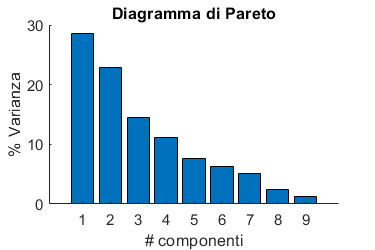

figure('position',[100 100 300 200])
bar(1:Nfeatures,100.*S./sum(S))
xlabel('# componenti')
ylabel('% Varianza')
title('Diagramma di Pareto')
box off

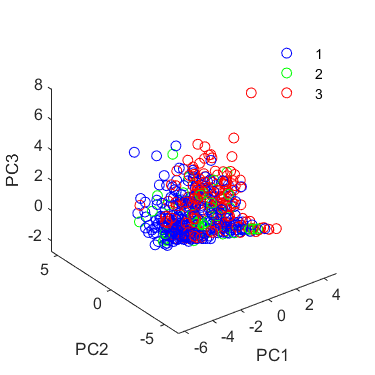

figure('Position',[100 100 300 300])
colori='bgr';
for i=1:Nclassi
   line(Xpc(indiciclassitrain{i},1),Xpc(indiciclassitrain{i},2),Xpc(indiciclassitrain{i},3),'color',colori(i),'linestyle','none','marker','o') 
end
axis equal
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
legend(class_labels)
legend boxoff
view(3)

Risulta ora di nostro interesse determinare quali sono le features più importanti, per la discriminazione di ciascuna coppia di classi.

Il metodo proposto è la LDA, ed in particolare è necessario determinare il discriminante di Fischer:

m1 ed m2 rappresentano le medie dei dati appartenenti alle due classi.

Sw invece è definita come "matrice di dispersione all'interno delle classi", calcolata sommando Sw1 ed Sw2, ovvero le covarianze dei dati appartenenti alle due classi, moltiplicate per il numero di campioni.

A questo punto per determinare la feature più importante per la discriminazione tra due classi, basta vedere quale è la componente maggiore di w, ed associarla alla feature corrispondente.

cont=0;
for i=1:Nclassi-1
for j=i+1:Nclassi
    cont=cont+1;
m1=mean(Xtrain(indiciclassitrain{i},:))';
m2=mean(Xtrain(indiciclassitrain{j},:))';
Sw1=cov(Xtrain(indiciclassitrain{i},:))*length(indiciclassitrain{i});
Sw2=cov(Xtrain(indiciclassitrain{j},:))*length(indiciclassitrain{j});
Sw=Sw1+Sw2;
w{cont}=inv(Sw)*(m1-m2);
end
end

### Classificatori

Avendo a disposizione il vettore delle feature, si vogliono realizzare dei modelli, che per ogni campione, prendano una decisione riguardo l'appartenenza di ognuno ad una delle possibili classi.

La decisione ottimale consiste nell'utilizzare un approccio Bayesiano, e quindi assegnare ad ogni campione, essendo w l'insieme delle Q possibili classi, l'appartenza alla classe che presenta la massima probabilità a posteriori.

I classificatori differiscono appunto nel metodo che utilizzano per stimare questa probabilità. 

Vengono di seguito realizzati cinque tipi di classificatori differenti.

NomeClassificatori=["Nb","Mln","SvmL","SvmNl","NN"];
nt=0;

### Naive Bayes

Il classificatore Naive Bayes appartiene ad una raccolta di algoritmi di classificazione basati sull'applicazione diretta del teorema di Bayes per quanto riguarda il calcolo della probabilità a posteriori.

Per il calcolo della massima probabilità a posteriori è necessario stimare per prima la probabilità class-condizionata p(x/wi), che è un problema di apprendimento non supervisionato, e nel nostro caso la consideriamo di tipo Gaussiano essendo la più comune.

nt=nt+1;
Nb=fitcnb(Xtrain,Ytrainclass,'DistributionNames','Normal'); 
[classpredictiontrain{nt,1},PosteriorTrain]=predict(Nb,Xtrain); 
[classpredictiontest{nt,1},PosteriorTest]=predict(Nb,Xtest);
Ytrain_pred{nt}=PosteriorTrain';
Ytest_pred{nt}=PosteriorTest';
[tpr,fpr,~] = roc(Y_class_ones_test,Ytest_pred{nt});
for cl=1:Nclassi
 auc(nt,cl) = sum(tpr{cl}(1:end-1).*diff(fpr{cl}));
end

#### Multi-Layer Network

Per quanto riguarda questo classificatore, il problema definisce:

- L'input layer, in cui ogni unità corrisponde ad una colonna del vettore delle features

- L'output layer, in cui ogni unità corrisponde ad una delle classi possibili per ogni campione

Ciò che invece bisogna stabilire, considerando un unico strato nascosto, consiste nel numero di neuroni dello strato nascosto.

L'approccio utilizzato per determinare il numero di neuroni nascosti ottimo consiste nel ricorrere alla Cross-validazione, e quindi creare delle reti neurali con tutti i numeri di neuroni dello strato nascosto possibili, calcolando per quanto riguarda i dati relativi al test-set, l'area sotto la curva ROC (AUC), per poi scegliere come numero di neuroni nascosti quello che mi fornisce una AUC più alta.

Per fare questo è necessario porre un limite superiore, al possibile numero di neuroni dello strato nascosto.

Una regola comunemente utilizzata per evitare problemi di over-fitting, consiste nel mantenere il numero di neuroni dello strato nascosto al di sotto di:

In cui Ni rappresenta il numero di neuroni in ingresso, No il numero di neuroni in uscita, Ns il numero di dati del training set, ed α un fattore di scala arbitrario compreso tra 5 e 10 (nel nostro caso viene posto pari a 5). [2]

Il problema di questo tipo di classificatori è che realizzando più volte l'addestramento, anche utilizzando lo stesso numero di neuroni nascosti, ottengo dei parametri del modello differenti, quindi non è detto che quelli trovati massimizzino la probabilità a posteriori.

La soluzione adottata per prevenire questo tipo di problema, è quella di applicare il metodo delle partenze multiple, e quindi ripetere più volte la costruzione della rete per poi prendere quella che fornisce le migliori performance in termini di AUC.

nt=nt+1;
Nhidmax=floor(Ntrain/(5*(Nfeatures+Nclassi)));
Numero_partenze=20;
for P=1:Numero_partenze
for Nhid=1:Nhidmax
    net=patternnet(Nhid); 
    neti{Nhid,P}=train(net,Xtrain',Y_class_ones_train);
    net1=neti{Nhid,P};
    Ytest_pred_auc=net1(Xtest');  
    [tpr,fpr,~]=roc(Y_class_ones_test,Ytest_pred_auc);
for cl=1:Nclassi
        auc2(Nhid,cl) = sum(tpr{cl}(1:end-1).*diff(fpr{cl}));
end
end
auc_multiple{P}=auc2;
end

for P=1:Numero_partenze
    auc_medie{P}=mean(auc_multiple{P}');
end

for P=1:Numero_partenze
[massime_auc(P),Numero_neuroni(P)]=max(auc_medie{P});
end

[auc_maggiore,partenza_corretta]=max(massime_auc);
net_tr = neti{Numero_neuroni(partenza_corretta),partenza_corretta};
Ytrain_pred{nt} = net_tr(Xtrain');
Ytest_pred{nt} = net_tr(Xtest');
[~ ,classpredictiontrain{nt,1}]=max(Ytrain_pred{nt});
[~,classpredictiontest{nt,1}]=max(Ytest_pred{nt});
[tpr,fpr,~] = roc(Y_class_ones_test,Ytest_pred{nt});
for cl=1:Nclassi
 auc(nt,cl) = sum(tpr{cl}(1:end-1).*diff(fpr{cl}));
end

#### Support Vector machines

Per quanto riguarda il caso in questione, in cui bisogna realizzare algoritmi che decidono l'appartenenza di un campione ad una delle tre classi a disposizione, si pone il problema dell'estendere il classificatore SVM, che è un classificatore binario, al caso multiclasse.

L'approccio utilizzato viene definito "one vs one" in cui si realizzano $\frac{\textrm{Nclassi}*\left(\textrm{Nclassi}-1\right)}{2}$ differenti classificatori, ognuno utilizzando i dati del training set, di ogni coppia di classi.

Per determinare la classe dei campioni appartenenti al test set, si applicano i dati a tutti i classificatori creati, e la decisione verrà fatta sulla base della classe più votata.

Per calcolare le prestazioni di questo classificatore, in termini di matrice di confusione e curva ROC, risulta necessario però ottenere la probabilità a posteriori globale, ,mentre si hanno a disposizione le probabilità a posteriori locali, ovvero quelle in uscita da ogni classificatore binario .

Per fare questo, si è utilizzato il metodo di Hamamura, che rappresenta una valida stima della probabilità a posteriori globale basato sull'assunzione che le funzioni discriminanti dei vari classificatori siano indipendenti tra loro, e che il valore delle probabilità a priori siano uguali tra loro [3].

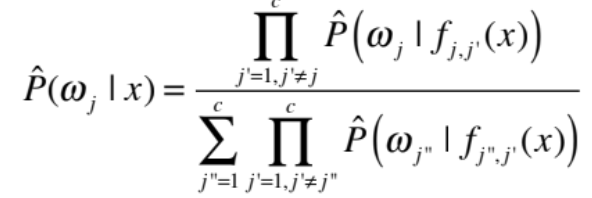

Si realizza quindi sia la SVM lineare, che quella non lineare, utilizzando un kernel di tipo "RBF" essendo il migliore in generale, ed anche il più utilizzato.

kernel=["linear","rbf"];
NumeroConfronti=(Nclassi*(Nclassi-1))/2;
for z=1:length(kernel)
    cont=0;
    for i=1:Nclassi-1
    for j=i+1:Nclassi
  indicitrain=sort([indiciclassitrain{i} ; indiciclassitrain{j}]);
  cont=cont+1;
  Xtr=Xtrain(indicitrain,:);
  Ytr=Ytrainclass(indicitrain,:);
 Ytr(Ytr==i)=0;
 Ytr(Ytr==j)=1;
  svm{z,cont} = fitcsvm(Xtr,Ytr,'KernelFunction',kernel(z));
  svm1{z,cont} = fitPosterior(svm{z,cont},'Holdout',0.10);
end
end 
end

for z=1:length(kernel)
choice=zeros(Ntrain,NumeroConfronti);
posterior={};
nt=nt+1;
for i=1:NumeroConfronti
[choice(:,i),posterior{i}] = predict(svm1{z,i},Xtrain);
end
cont=0;
for i=1:NumeroConfronti-1
    for j=i+1:NumeroConfronti
        cont=cont+1;
        A=find(choice(:,cont)==1);
        B=find(choice(:,cont)==0);
        choice(A,cont)=j;
        choice(B,cont)=i;
    end
end    
posterior12=posterior{1};
posterior13=posterior{2};
posterior23=posterior{3};
Denominatore=posterior12(:,1).*posterior13(:,1)+posterior12(:,2).*posterior23(:,1)+posterior13(:,2).*posterior23(:,2);
posterior1=(posterior12(:,1).*posterior13(:,1))./Denominatore;
posterior2=(posterior12(:,2).*posterior23(:,1))./Denominatore;
posterior3=(posterior13(:,2).*posterior23(:,2))./Denominatore;
posteriorsvm=[posterior1 posterior2 posterior3];
Ytrain_pred{nt}=posteriorsvm';
classpredictiontrain{nt,1}=mode(choice');
end

nt=nt-2;
for z=1:length(kernel)
choice=zeros(Ntest,NumeroConfronti);
posterior={};
nt=nt+1;
for i=1:NumeroConfronti
[choice(:,i),posterior{i}] = predict(svm1{z,i},Xtest);
end
cont=0;
for i=1:NumeroConfronti-1
    for j=i+1:NumeroConfronti
        cont=cont+1;
        A=find(choice(:,cont)==1);
        B=find(choice(:,cont)==0);
        choice(A,cont)=j;
        choice(B,cont)=i;
    end
end    
posterior12=posterior{1};
posterior13=posterior{2};
posterior23=posterior{3};
Denominatore=posterior12(:,1).*posterior13(:,1)+posterior12(:,2).*posterior23(:,1)+posterior13(:,2).*posterior23(:,2);
posterior1=(posterior12(:,1).*posterior13(:,1))./Denominatore;
posterior2=(posterior12(:,2).*posterior23(:,1))./Denominatore;
posterior3=(posterior13(:,2).*posterior23(:,2))./Denominatore;
posteriorsvm=[posterior1 posterior2 posterior3];
Ytest_pred{nt}=posteriorsvm';
classpredictiontest{nt,1}=mode(choice');
[tpr,fpr,~] = roc(Y_class_ones_test,Ytest_pred{nt});
for cl=1:Nclassi
 auc(nt,cl) = sum(tpr{cl}(1:end-1).*diff(fpr{cl}));
end
end

#### K-nearest-neighbours

Per utilizzare questo tipo di algoritmo, è necessario specificare un determinato "numero di vicini", pari a K.

Nel momento in cui si realizza la decisione per quanto riguarda l'appartenenza di un campione, ad una determinata classe, l'algoritmo sceglie in base alla classe maggiormente presente nei K dati utilizzati per il training, che si trovano più vicini ad esso.

In realtà non esiste un metodo esatto per determinare il migliore valore di K.

La scelta di valori bassi per K può portare a risultati rumorosi, mentre la scelta di alti valori di K porta ad avere un alto Bias, per questo di norma il valore più comunemente utilizzato è  $K=\sqrt{\textrm{Ntrain}}$

nt=nt+1;
NN=fitcknn(Xtrain,Ytrainclass,'NumNeighbors',floor(sqrt(Ntrain)));
[classpredictiontrain{nt,1},PosteriorTrain]=predict(NN,Xtrain);
[classpredictiontest{nt,1},PosteriorTest]=predict(NN,Xtest);
Ytrain_pred{nt}=PosteriorTrain';
Ytest_pred{nt}=PosteriorTest';
[tpr,fpr,~] = roc(Y_class_ones_test,Ytest_pred{nt});
for cl=1:Nclassi
 auc(nt,cl) = sum(tpr{cl}(1:end-1).*diff(fpr{cl}));
end

## Presentazione dei risultati

#### Matrici di confusione (Train)

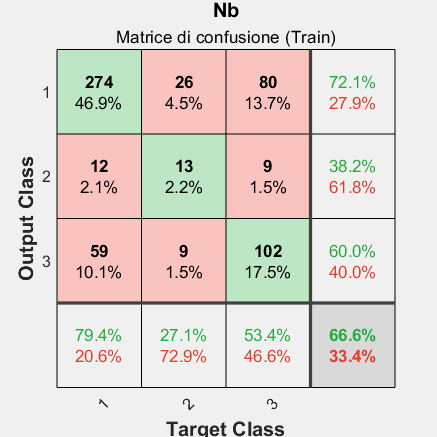

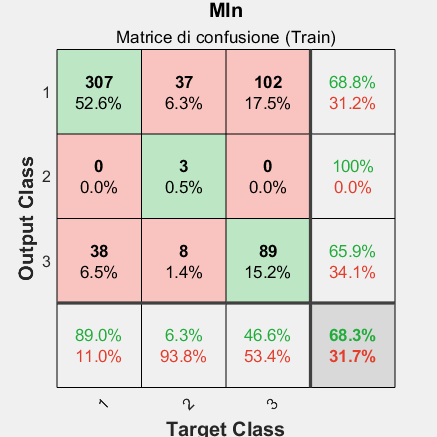

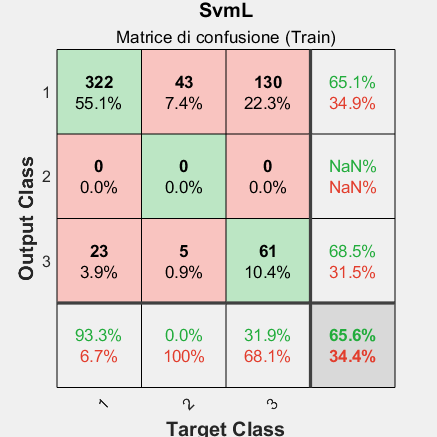

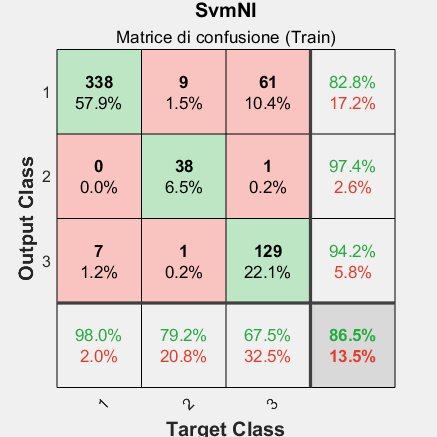

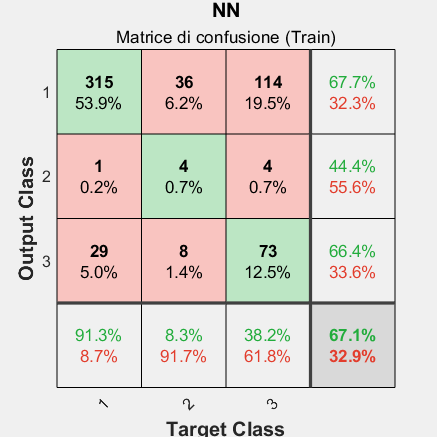

for i = 1 : nt
    figure
plotconfusion(Y_class_ones_train,Ytrain_pred{i})
title(NomeClassificatori{i},"Matrice di confusione (Train)")
set(gcf,'pos',[0 0 350 350])
end

#### Matrici di confusione (Test)

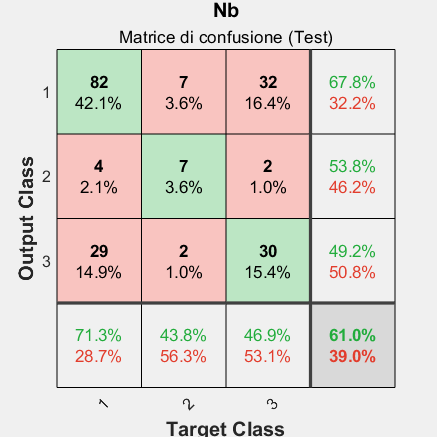

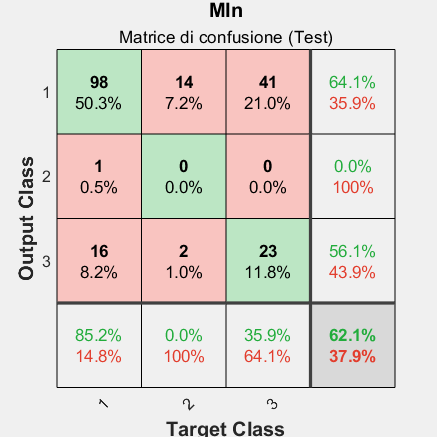

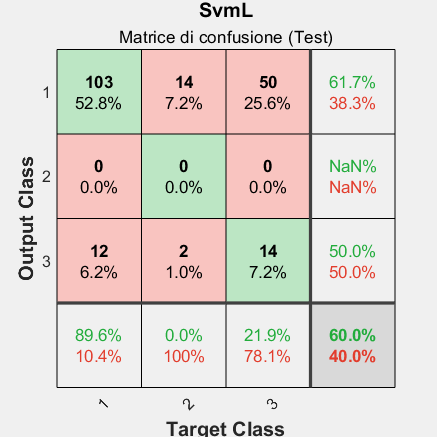

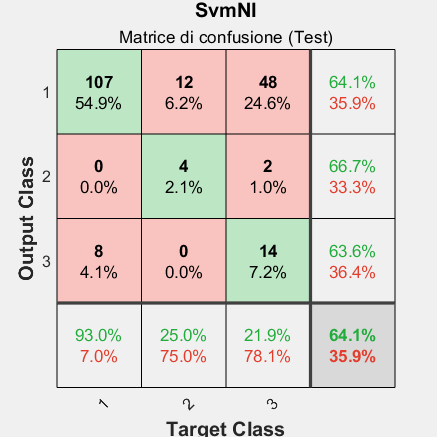

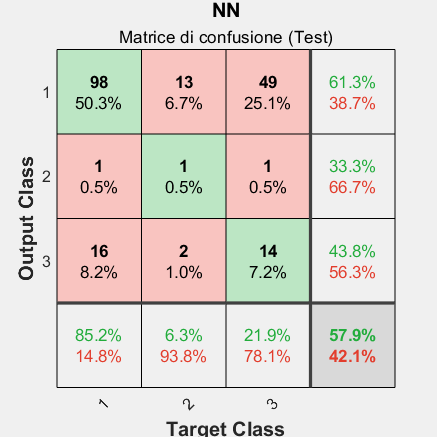

for i = 1 : nt
    figure
plotconfusion(Y_class_ones_test,Ytest_pred{i})
title(NomeClassificatori{i},"Matrice di confusione (Test)")
set(gcf,'pos',[0 0 350 350])
end

#### Curve ROC

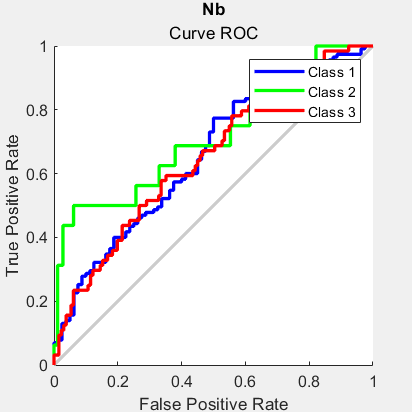

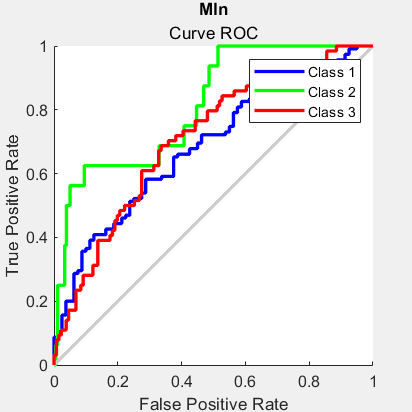

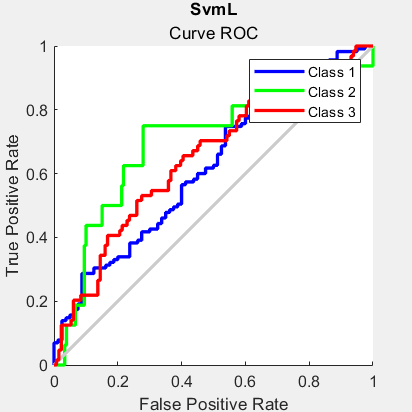

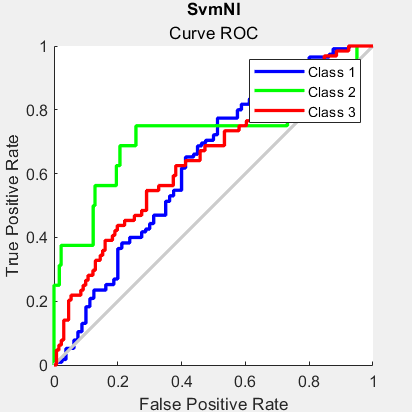

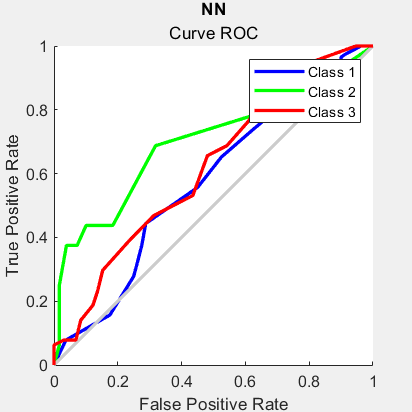

for i = 1 : nt
    figure
plotroc(Y_class_ones_test,Ytest_pred{i})
title(NomeClassificatori{i},"Curve ROC")
set(gcf,'pos',[0 0 330 330])
end

#### AUC delle singole classi

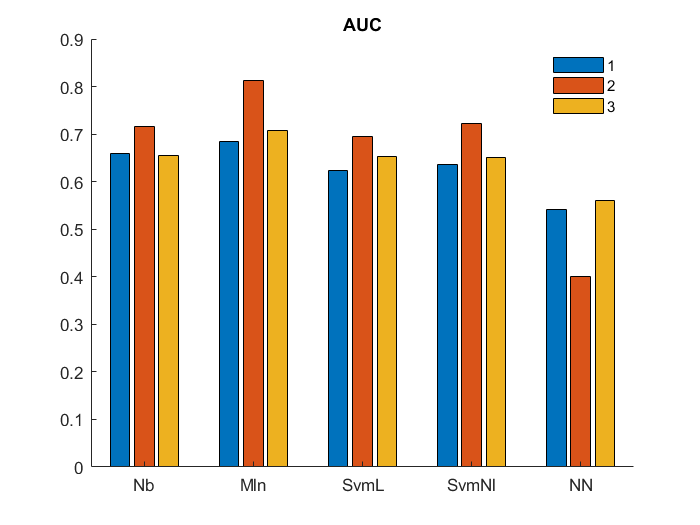

figure
bar(auc)
box off
xticklabels(NomeClassificatori)
legend(class_labels)
legend boxoff
title('AUC')

####     AUC Mediata sulle tre classi

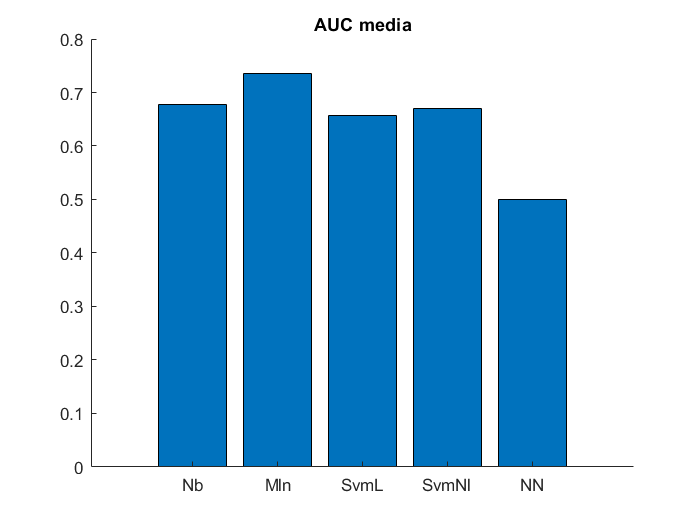

figure
bar(mean(auc'))
box off
xticklabels(NomeClassificatori)
title('AUC media')

#### Classe predetta da ogni classificatore

nt=nt+1;
classpredictiontrain{nt,1}=Ytrainclass;
classpredictiontest{nt,1}=Ytestclass;
for i=1:nt
    classpredictiontest{i}=reshape(classpredictiontest{i},1,Ntest);
    classpredictiontrain{i}=reshape(classpredictiontrain{i},1,Ntrain);
end
name=[NomeClassificatori "Classe esatta"]';
Test=cell2table(classpredictiontest,'RowNames',name)

Test = 6×1 table
                     classpredictiontest
                     ___________________

    Nb                 [1×195 double]   
    Mln                [1×195 double]   
    SvmL               [1×195 double]   
    SvmNl              [1×195 double]   
    NN                 [1×195 double]   
    Classe esatta      [1×195 double]   


Train=cell2table(classpredictiontrain,'RowNames',name)

Train = 6×1 table
                     classpredictiontrain
                     ____________________

    Nb                  [1×584 double]   
    Mln                 [1×584 double]   
    SvmL                [1×584 double]   
    SvmNl               [1×584 double]   
    NN                  [1×584 double]   
    Classe esatta       [1×584 double]   


#### Numero di neuroni dello strato nascosto utilizzati

fprintf('il numero di neuroni dello strato nascosto utilizzato è %d .\n',Numero_neuroni(partenza_corretta))

il numero di neuroni dello strato nascosto utilizzato è 2 .


#### Feature più importanti per le discriminazioni tra classi

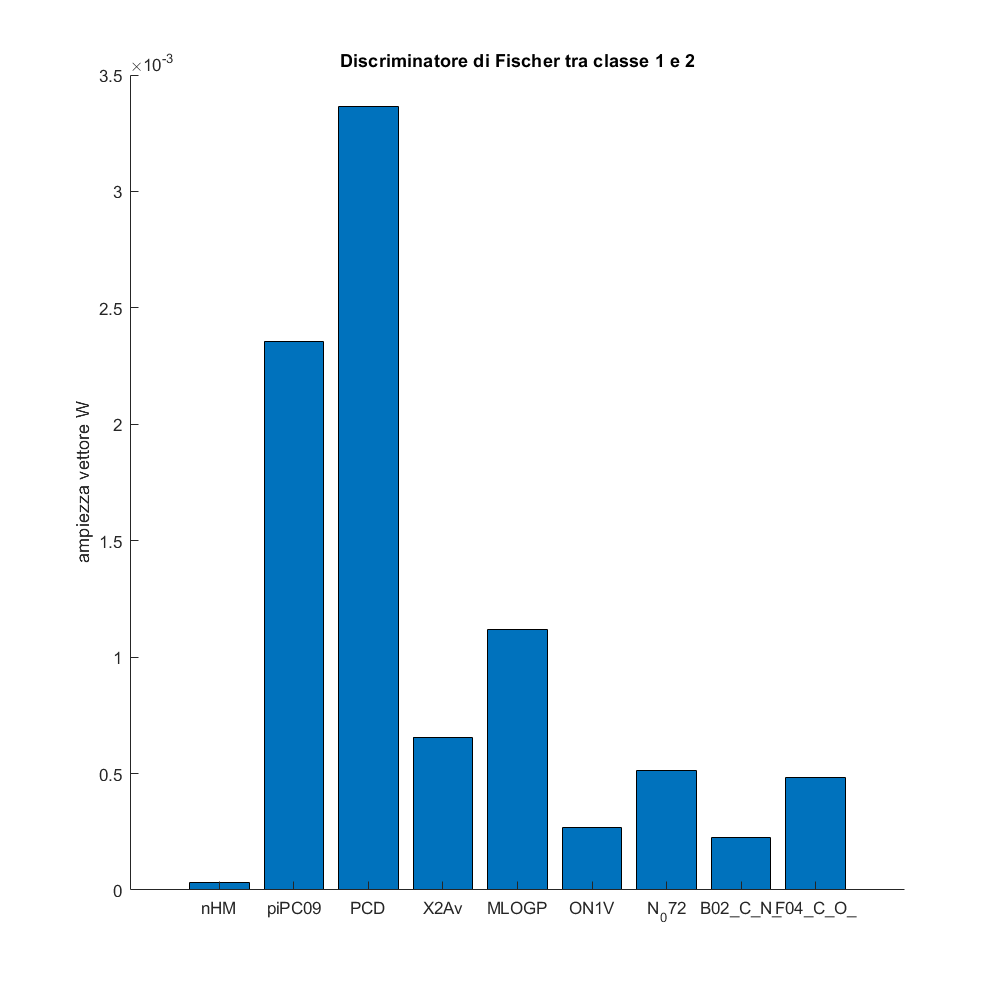

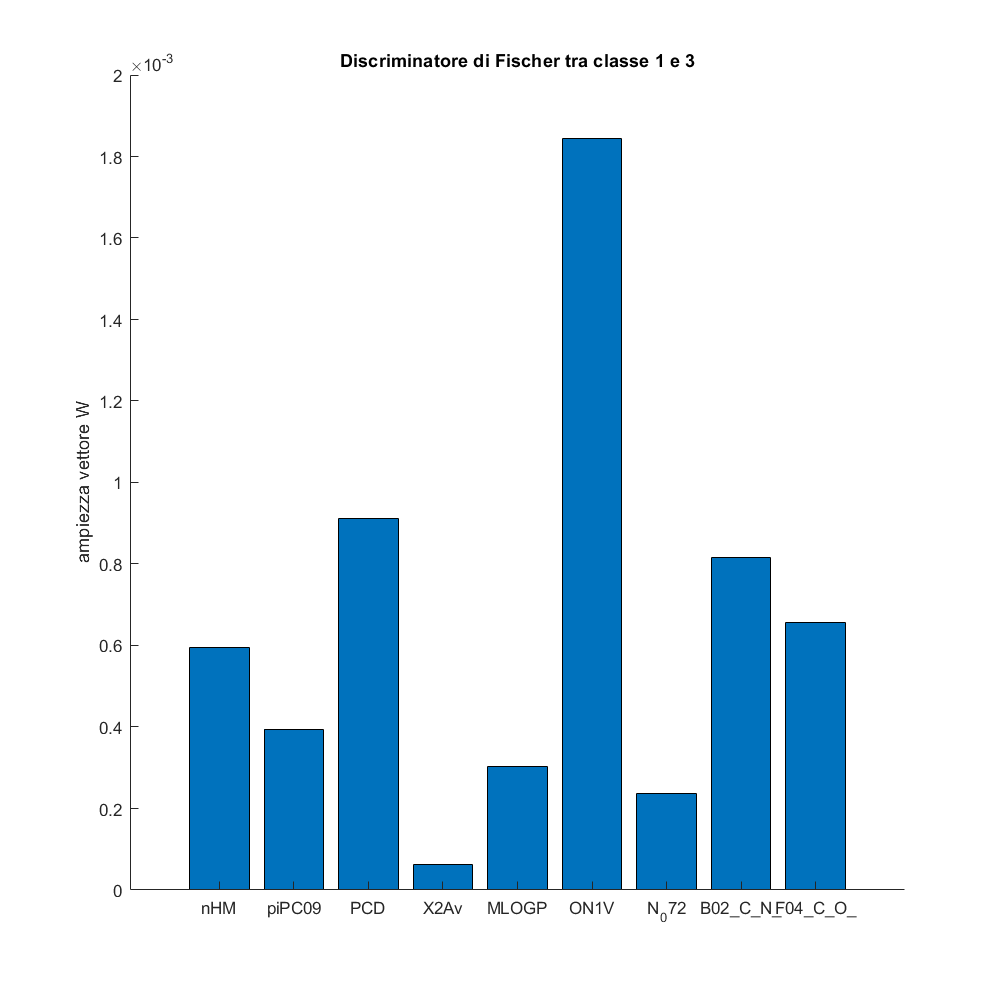

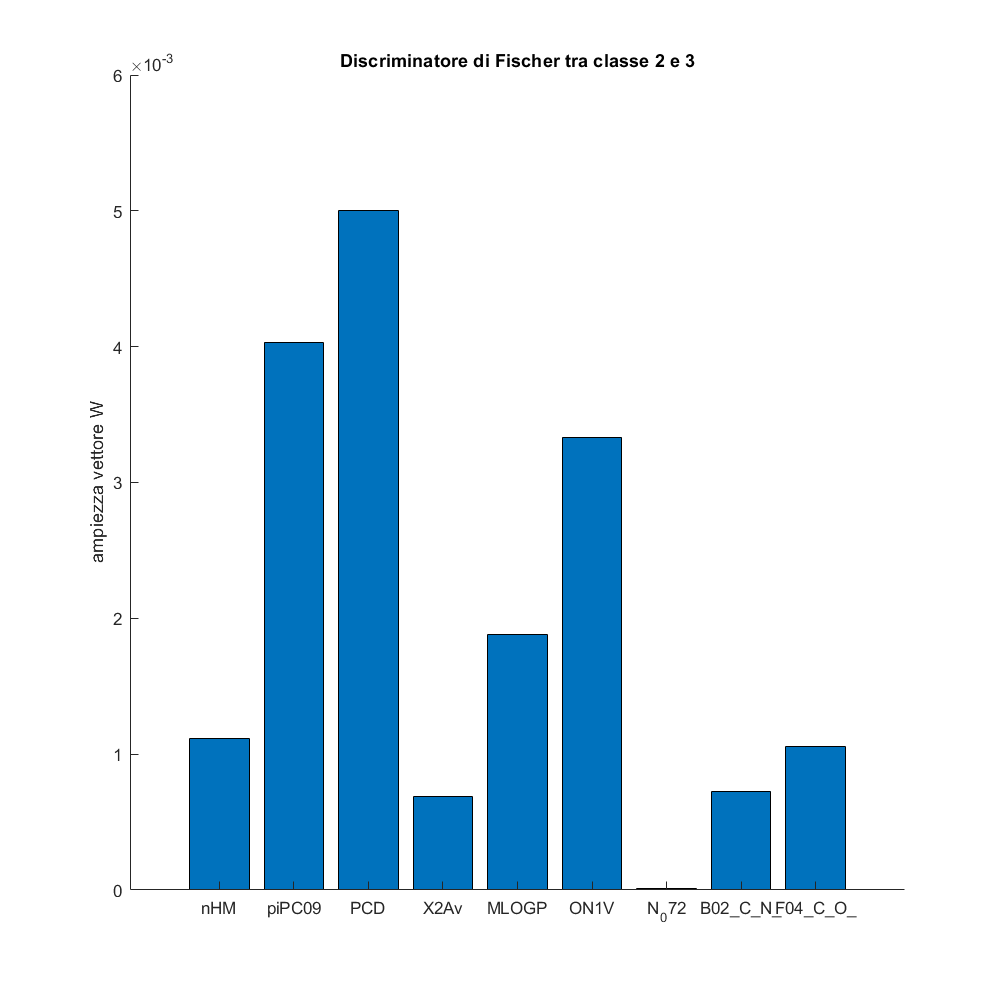

cont=0;
for i=1:Nclassi-1
    for j=i+1:Nclassi
       cont=cont+1; 
        figure('Position',[0 0 800 800])
       bar(abs(w{cont}))
       box off
       classe1confronto=string(i);
       classe2confronto=string(j);
       titolo=strcat("Discriminatore di Fischer tra classe ",classe1confronto," e ",classe2confronto);
       title(titolo)
       ylabel('ampiezza vettore W')
       xticklabels(features_labels)
    end
end

### Conclusioni

Il primo passo è consistito nel visualizzare i dati a disposizione, realizzando una riduzione di dimensione tramite l'utilizzo della PCA.

A partire dal diagramma di Pareto, è possibile notare che, visualizzando i dati in tre dimensioni, si visualizza soltanto il 65,911% dell'informazione disponibile.

Si può quindi notare dal grafico che i dati in questione non sembrano essere linearmente separabili, rendendo difficile ipotizzare quali siano le feature che discriminano tra le varie classi mediante il grafico "biplots".

Per risolvere il problema si è utilizzata quindi la LDA, in modo da concludere che la feature "PCD" è quella maggiormente determinante per discriminare la classe 2, dalle altre, mentre per discriminare tra classe 1 e classe 3, la feature più importante risulta la "ON1V"

Si sono succesivamente implementati i classificatori che, utilizzando i dati a disposizione, prendono una decisione ed  associano ogni campione alla classe corrispondente.

Per determinare le performance dei singoli classificatori si è utilizzato come criterio, non volendo appunto avere a che fare con classificatori che siano più o meno conservativi nei confronti di una determinata classe, l'area sotto la curva ROC.

Seguendo questo principio, il classificatore che offre le migliori performance risulta essere l'MLN, se si sceglie un numero di partenze multiple piuttosto alto, mentre il peggiore risulta essere il K-NN.

In ogni caso, dato che la AUC minima possibile di un classificatore risulta essere 0.5, mentre la massima pari ad 1, si può concludere che i classificatori utilizzati non offrono performance molto buone.

In termini di percentuale di decisioni corrette invece, il classificatore SVM non lineare, risulta nettamente migliore rispetto gli altri per quanto riguarda i dati appartenenti al training set, mentre non esistono differenze significative per quanto riguarda quelli appartenenti al test set.

Osservando le matrici di confusione si può osservare quindi come la maggior parte delle sostanze analizzate tendono a concentrarsi principalmente all'interno dei tessuti lipidici, mentre soltanto poche di esse saranno concentrate all'interno di altri tessuti.

### Bibliografia

[1]: F. Grisoni, V.Consonni, M.Vighi, S.Villa, R.Todeschini (2016). Investigating the mechanisms of bioconcentration through QSAR classification trees, Environment International, 88, 198-205

[3]: J. Milgram, M.Cheriet, R.Sabourin (2006). “One Against One” or “One Against All”: Which One is Better for Handwriting Recognition with SVMs?

### Sitografia

[2]: https://www.solver.com/training-artificial-neural-network-intro